clear;
n=2;
coordinate=sym("u%d",[n,1]);
M=coordinate(1)^2+coordinate(2)^2;

X=[ 2*coordinate(1)/(1+M)
    2*coordinate(2)/(1+M)
    (M-1)/(M+1)];
uinterval=[-5,5];
vinterval=[-5,5];
hh=hjs("n",n,"coordinate",coordinate,"X",X);

hh();
hh.g

$$ans = \left(\begin{array}{cc} \frac{4}{{\left({u_{1}}^{2}+{u_{2}}^{2}+1\right)}^{2}} & 0\\ 0 & \frac{4}{{\left({u_{1}}^{2}+{u_{2}}^{2}+1\right)}^{2}} \end{array}\right)$$

hh.connection

$$\left(\begin{array}{cc} -\frac{2\,u_{1}}{{u_{1}}^{2}+{u_{2}}^{2}+1} & -\frac{2\,u_{2}}{{u_{1}}^{2}+{u_{2}}^{2}+1}\\ \frac{2\,u_{2}}{{u_{1}}^{2}+{u_{2}}^{2}+1} & -\frac{2\,u_{1}}{{u_{1}}^{2}+{u_{2}}^{2}+1} \end{array}\right)$$

$$\left(\begin{array}{cc} -\frac{2\,u_{2}}{{u_{1}}^{2}+{u_{2}}^{2}+1} & \frac{2\,u_{1}}{{u_{1}}^{2}+{u_{2}}^{2}+1}\\ -\frac{2\,u_{1}}{{u_{1}}^{2}+{u_{2}}^{2}+1} & -\frac{2\,u_{2}}{{u_{1}}^{2}+{u_{2}}^{2}+1} \end{array}\right)$$

hh.curvature_tensor();
hh.Scalar_curvature

$$ans = 2$$

hh.Gauss_curvature

$$ans = 1$$

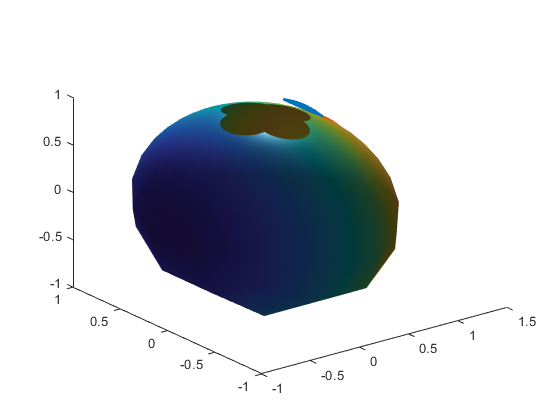

hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0.1+t;0];
% hh.scale=0;
hh.parallel_transport(u,[0;3],[1,1],30);

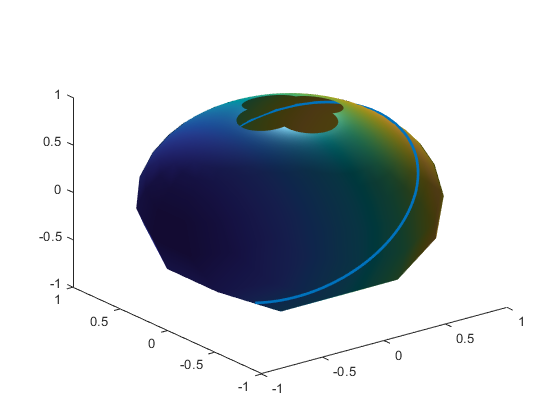

figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,30],[0.1, 0.1, 1, 0],100);